## Ejercicio 1

El archivo de simulink contiene el modelo de un vehículo que aterriza verticalmente usando un motor propulsor. El objetivo de control es descender a una velocidad  constante de -50 m/s. El controlador ya fue diseñado con un PI y está funcionando  correctamente.

**Problema:** la acción de control en valor absoluto supera  10^5 N, que es la máxima fuerza que puede hacer el motor. 

**Tarea:** Modifique la estructura del controlador PI de manera tal que la dinámica a lazo cerrado frente a las  perturbaciones permanezca igual, pero que la dinámica  frente a los escalones de la referencia se suavice. Luego de la modificación, la acción de control no  debería superar los 9 * 10^4 N.

**Resolucion: **reconectar Kp

## Ejercicio 2

Formule la planta en espacio de estados donde la salida sea la posición y donde el vector de estado sea

x = [ p

      v ]

p = posición

v = velocidad

u = acción de control

d = perturbaciones

fg = fuerza de la gravedad

clc; clear; close all

%% Solución
% a = p_ddot = v_dot
% m*a = - v*c - fg + u + d

% p_dot = ...
% v_dot = ...
% 
% x1_dot = x2
% x2_dot = ...

g = 9.8;
m = 1000;
c = 100;
fg = m*g;      % magnitud positiva del peso

% velocidad terminal esperada
v_term = -fg/c

v_term = -98


A = [0 1;
     0 -(c/m)];

Bu = [0; 1/m];
Bd = [0; -1/m];

C = [1 0];     % salida posición
D = 0;

  


Simulación a lazo abierto debe verificarse que la velocidad terminal a  lazo abierto sea -98 m/s

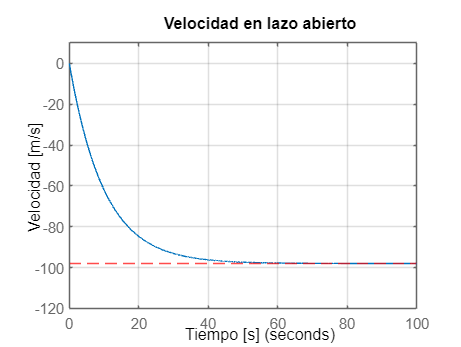

%% Verificación de velocidad terminal
% Para ver velocidad, uso C_v en vez de C
C_v = [0 1];

sis_lazo_abierto = ss(A, Bd, C_v, D);

t = 0:0.01:100;

% Como Bd ya tiene signo negativo, la entrada debe ser +fg
fg_t = fg*ones(size(t));

figure
lsim(sis_lazo_abierto, fg_t, t)
grid on
yline(-98,'--r')
title('Velocidad en lazo abierto')
xlabel('Tiempo [s]')
ylabel('Velocidad [m/s]')
ylim([-120 10])

  
%% Entrega: PARCIAL_2_Apellido_E2.m


m*a = -v*c - Fg + u + d

 ||

 \/

x1 = x

x2=x1_dot = v

x2_dot=x1_dot_dot = a

 ||

 \/

m*x2_dot = -x2*c - Fg + u + d;

x2_dot = x2*(-c/m) - Fg/m + u/m + d/m;

x1_dot = x2

 ||

 \/

A,BFg,Bu,Bd,C,D (D=[0])

Factor comun B => B*(-Fg+C+D)